# **AUTOMATED SIMULATION**

In this file we are going to analize two kind of controllers. In the first part we deal with anti-windup and feedforward, while in the second one we exploit the power of state-space techniques. This forst section clears the workspace and loads all the paramters that aree needed to perform simulations.

clear all
clc;

load('parameters.mat');
warning('off','all')

## 2.1 Simulink model of DC gearbox + resonant load

## Bias removal

It is really important to determine this value in order to make the correct readings for the next estiamation (otherwise when taking into consideration the abs(theta)) the graph is not correctly centered.

bias.BB = out.bias.signals.values(1000);
disp(bias.BB)
save('Bias.mat',"bias")

P =
 
           6.429e-06 s^2 + 1.561e-05 s + 0.003811
  ---------------------------------------------------------
  4.089e-08 s^4 + 1.373e-06 s^3 + 0.0002846 s^2 + 0.00138 s
 
Continuous-time transfer function.



## Estimation of the elastic joint parameters

Assume that the hub is kept fixed (i.e. ωh = 0). Moreover, assume that no external disturbance torque is applied to the beam. Typically δ < 1, so we have underdamped second order system with no external forcing.  Fisrt of all we have to acquire data in order to use them to compute the regression. 

Estimate bias first, then insert the correct value into the model. The run a simulation at the desired angles deflection

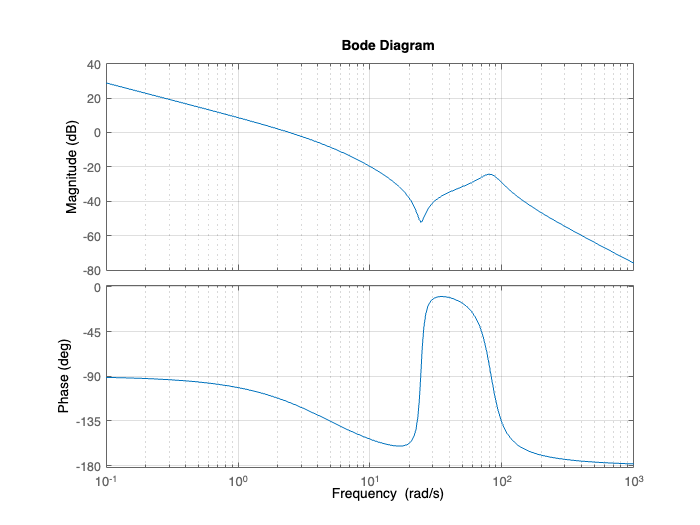

load Bias.mat
regression.theta_deflection = 18;

estimation.BB = sim('estimator_BB','StartTime','0','StopTime','5','AlgebraicLoopMsg', 'off');

magPwg = 0.0257

phasePwg = -160.3116

Figure to check we considering a correct evolution of the displacement

figure
plot(estimation.BB.thd_est.time, abs(estimation.BB.thd_est.signals.values))
hold on
plot(estimation.BB.thd_est.time, estimation.BB.thd_est.signals.values,'--', LineWidth=0.1)
xlabel('Time[s]')
ylabel('|\theta_d| [deg]')
xlim([0 2])

Firts consider the number of measures we want to take and then build the vectors for regression

regression.nmeas = 11;
regression.y = zeros(regression.nmeas,1);
regression.phi = zeros(regression.nmeas,2);

     a: 20
     K: 36.6681
    Kd: 1.0076
    Ki: 66.7216



Build vectors

Pay attention - when considering the value of theta with the time you must rount becuase we are considering indices

i = 1;
while(i<= regression.nmeas)
    regression.phi(i,:) = [-i, 1];
    regression.y(i,1) = log(abs(estimation.BB.thd_est.signals.values(regression.t*1000*i)));
    i = i+1;
end

regression.theta = lsqr(regression.phi,regression.y);
disp(regression.theta)
regression.d = regression.theta(1)/sqrt(regression.theta(1)^2 + pi^2);

ans = struct with fields:
         RiseTime: 0.2076
    TransientTime: 2.0819
     SettlingTime: 2.0819
      SettlingMin: 38.8800
      SettlingMax: 50.2200
        Overshoot: 0.4400
       Undershoot: 0
             Peak: 50.2200
         PeakTime: 3.4770


disp(regression.d)

In order to estimate the correct frequency we need to determine the distance amont two consecutives peaks. To do so, fisrt we smooth the orignal signal, then we find peaks and consequently the distance among them.

Check if this smoothing removes the firts peak. This is handled cosequently.

regression.smooth_signal = smoothdata(abs(estimation.BB.thd_est.signals.values),'gaussian',20);

Figure to check  the effect of smoothing on the signal

figure

ans = struct with fields:
         RiseTime: 0.9713
    TransientTime: 2.2703
     SettlingTime: 2.2703
      SettlingMin: 108.1800
      SettlingMax: 120.2400
        Overshoot: 0.2000
       Undershoot: 0
             Peak: 120.2400
         PeakTime: 4.2930


plot(estimation.BB.thd_est.time, regression.smooth_signal)
hold on
plot(estimation.BB.thd_est.time, abs(estimation.BB.thd_est.signals.values),'--')

xlabel('Time[s]')

ans = struct with fields:
         RiseTime: 0.2076
    TransientTime: 2.0819
     SettlingTime: 2.0819
      SettlingMin: 38.8800
      SettlingMax: 50.2200
        Overshoot: 0.4400
       Undershoot: 0
             Peak: 50.2200
         PeakTime: 3.4770


ylabel('|\theta_d| [deg]')
xlim([0 2])

%[pks1,locs1] = findpeaks(regression.smooth_signal,'MinPeakDistance',0.1);

ans = struct with fields:
         RiseTime: 0.9713
    TransientTime: 2.2703
     SettlingTime: 2.2703
      SettlingMin: 108.1800
      SettlingMax: 120.2400
        Overshoot: 0.2000
       Undershoot: 0
             Peak: 120.2400
         PeakTime: 4.2930


%[pks,locs] = findpeaks(regression.smooth_signal,'MinPeakDistance',0.1);
%disp(pks)
%disp(locs)
figure
findpeaks(regression.smooth_signal,'MinPeakDistance',1)

text(locs+.02,pks,num2str((1:numel(pks))'))


## **2.2 Position PID control**

− perfect steady–state tracking of step position references (hub side)

− perfect steady–state rejection of constant torque disturbances (hub side)

− step response (hub side) with settling time ts,5% ≤ 0.85 s and overshoot Mp ≤ 30%.

Now we have to determine the transfer function from

s = tf('s');
Dp = estimated.Jeq*beam.Jb*s^3 + (estimated.Jeq*beam.Bb+beam.Jb*estimated.Beq)*s^2 + (estimated.Beq*beam.Bb + joint.k*(estimated.Jeq + beam.Jb/(gbox.N^2)))*s + joint.k*(estimated.Beq + beam.Bb/(gbox.N^2));
P = drv.dcgain*mot.Kt*(beam.Jb*s^2 + beam.Bb*s + joint.k)/((gbox.N*s)*((sens.curr.Rs+mot.R)*Dp + mot.Ke*mot.Ke*(beam.Jb*s^2 + beam.Bb*s + joint.k)))

We explot Bode Method to determine PID parameters

% Get magnitue and phase at the desired frequency
bode(P)
grid on
[magPwg, phasePwg] = bode(P, perf.wg)
dK = abs(magPwg)^-1;
dPh = -pi + perf.phi*deg2rad - phasePwg*deg2rad;

pid.a = 20;                 
pid.K = dK * cos(dPh);
Td = (tan(dPh)+sqrt(tan(dPh)^2+4/pid.a))/(2*perf.wg);
Ti = pid.a*Td;

pid.Kd = pid.K*Td;
pid.Ki = pid.K/Ti;
disp(pid)

Determine real derivative paramters for the PID

der.Tl = 1/(10*perf.wg);

Determine anti-windup parameters

awu.Tw = perf.ts5/5;
awu.Kw = 1/awu.Tw;

Simulations for the PID on the **real motor** model

Notice that the initial choice of a = 4 does not satisfy specs on the real motor. We need at least a = 20

simul.stepdeg = 50;
PID.real.deg_50 = sim('PID_Real','StartTime','0','StopTime','10','AlgebraicLoopMsg', 'off');
stepinfo(PID.real.deg_50.thh_meas.signals.values,PID.real.deg_50.thh_meas.time, simul.stepdeg,'SettlingTimeThreshold', 0.05)
simul.stepdeg = 120;
PID.real.deg_120 = sim('PID_Real','StartTime','0','StopTime','10','AlgebraicLoopMsg', 'off');
stepinfo(PID.real.deg_120.thh_meas.signals.values,PID.real.deg_120.thh_meas.time, simul.stepdeg,'SettlingTimeThreshold', 0.05)

Simulations for the PID on the **BB** model

simul.stepdeg = 50;
PID.BB.deg_50 = sim('PID_Real','StartTime','0','StopTime','10','AlgebraicLoopMsg', 'off');
stepinfo(PID.BB.deg_50.thh_meas.signals.values,PID.BB.deg_50.thh_meas.time, simul.stepdeg,'SettlingTimeThreshold', 0.05)
simul.stepdeg = 120;
PID.BB.deg_120 = sim('PID_Real','StartTime','0','StopTime','10','AlgebraicLoopMsg', 'off');
stepinfo(PID.BB.deg_120.thh_meas.signals.values,PID.BB.deg_120.thh_meas.time, simul.stepdeg,'SettlingTimeThreshold', 0.05)

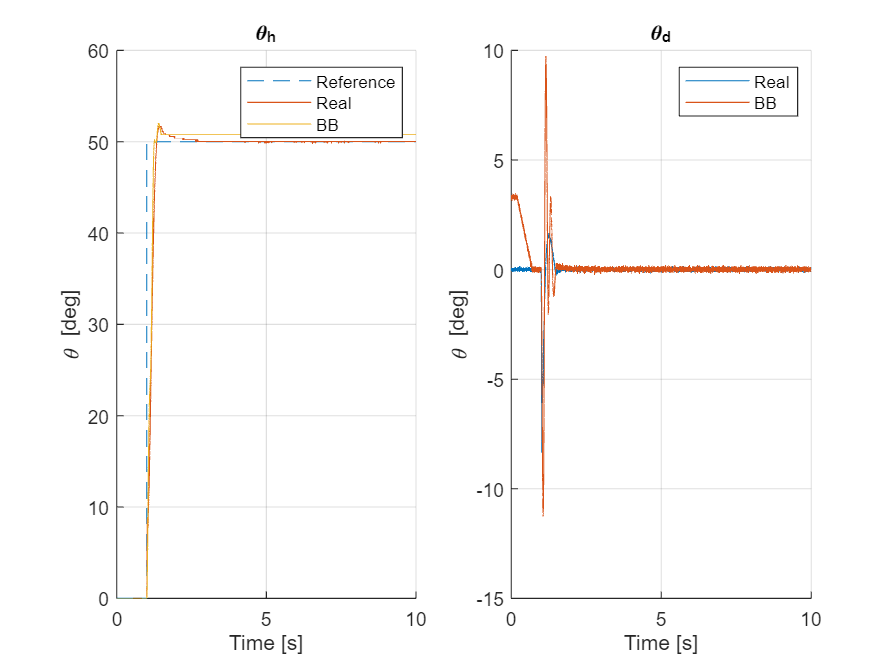

save('PID.mat','PID');

## **2.3 State space control**

For all the simulation in this part of the Lab we will need the same reference input

simul.stepdeg = 50;

#### Nominal state space

ss_nominal.wn = perf.wg;
ss_nominal.d = perf.d;
ss_nominal.phi = atan(sqrt(1-ss_nominal.d^2)/perf.d);
%ss_nominal.poles = -[exp(1i*ss_nominal.phi/2) exp(-1i*ss_nominal.phi/2) exp(1i*ss_nominal.phi) exp(-1i*ss_nominal.phi) ].*ss_nominal.wn;
ss_nominal.poles =[-30-5*1i -30+5*1i -35-5*1i -35+5*1i];
ss_nominal.K = real(place(SS.A, SS.B, ss_nominal.poles));
ss_nominal.N = [SS.A SS.B; SS.C SS.D]\[zeros(4,1); 1];
ss_nominal.Nx = ss_nominal.N(1:4);
ss_nominal.Nu = ss_nominal.N(5);

ss_nominal.real_model = sim('SS_Nominal_Real','StartTime','0','StopTime','10','AlgebraicLoopMsg', 'off');
ss_nominal.BB = sim('SS_Nominal_BB','StartTime','0','StopTime','10','AlgebraicLoopMsg', 'off');

figure
subplot(1,2,1);
hold on;
plot(ss_nominal.real_model.thh_ref.time, ss_nominal.real_model.thh_ref.signals.values,'--');
plot(ss_nominal.real_model.thh_meas.time, ss_nominal.real_model.thh_meas.signals.values);
plot(ss_nominal.BB.thh_est.time, ss_nominal.BB.thh_est.signals.values);
legend('Reference', 'Real', 'BB')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('\theta_h')

subplot(1,2,2);
hold on;
plot(ss_nominal.real_model.thd_meas.time, ss_nominal.real_model.thd_meas.signals.values);
plot(ss_nominal.BB.thd_est.time, ss_nominal.BB.thd_est.signals.values);
legend('Real', 'BB')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('\theta_d')

#### Robust State Space

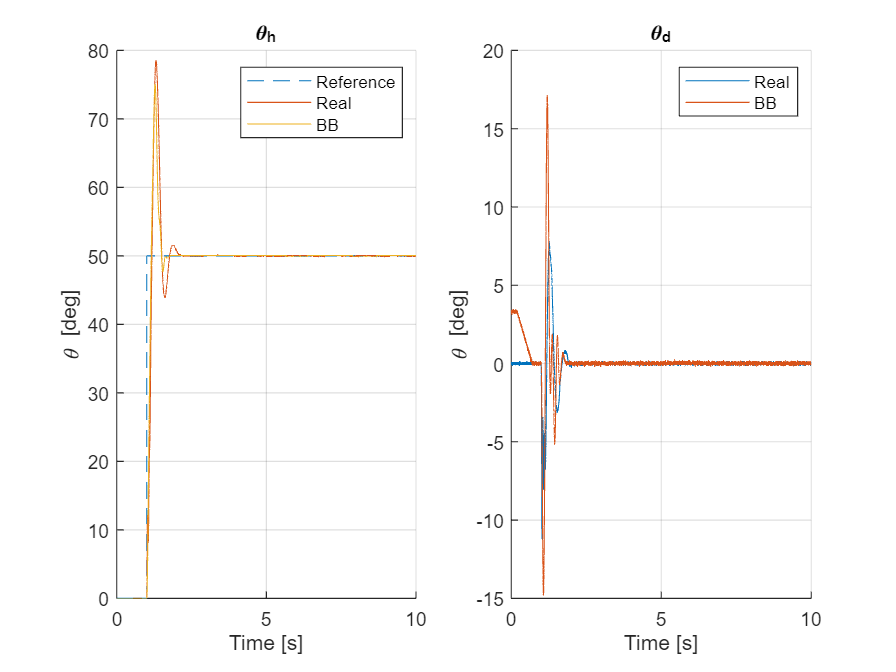

ss_robust.wn = perf.wg;
ss_robust.d = perf.d;
ss_robust.phi = atan(sqrt(1-ss_robust.d^2)/perf.d);

ss_robust.N = [SS.A SS.B; SS.C SS.D]\[zeros(4,1); 1];
ss_robust.Nx = ss_robust.N(1:4);

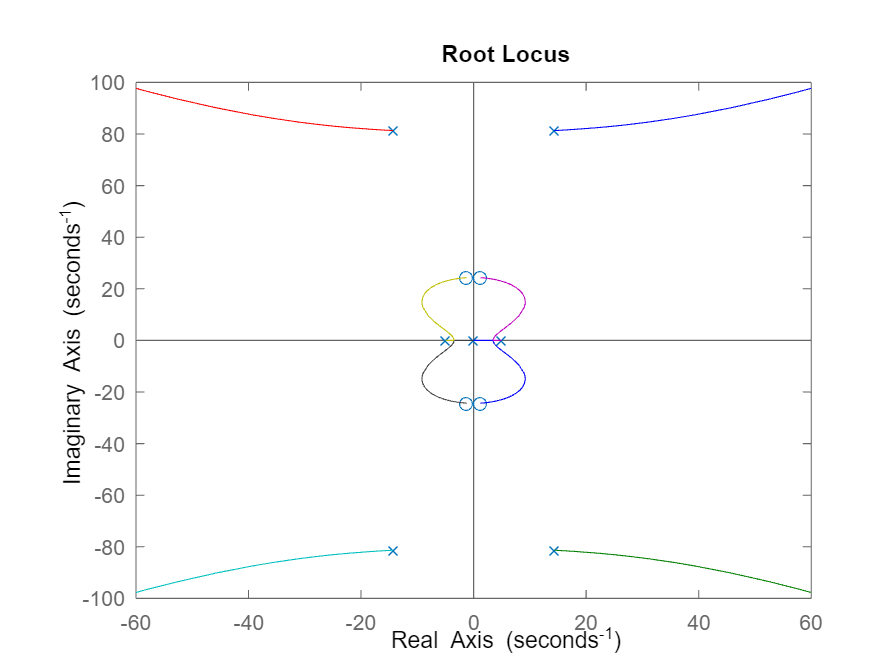

ss_robust.Nu = ss_robust.N(5);
ss_robust.Ae = [0 SS.C; zeros(4,1) SS.A];
ss_robust.Be = [0; SS.B];
ss_robust.Ce = [0 SS.C];

%ss_robust.poles = -[exp(1i*ss_robust.phi/2) exp(-1i*ss_robust.phi/2) exp(1i*ss_robust.phi) exp(-1i*ss_robust.phi) 1].*ss_robust.wn;
ss_robust.poles = [-25-5*1i -25+5*1i -30-5*1i -30+5*1i -25];
ss_robust.Ke = place(ss_robust.Ae, ss_robust.Be, ss_robust.poles);
ss_robust.Ki = ss_robust.Ke(1);
ss_robust.K = ss_robust.Ke(2:5);

ss_robust.real_model = sim('SS_Robust_Real','StartTime','0','StopTime','10','AlgebraicLoopMsg', 'off');
ss_robust.BB = sim('SS_Robust_BB','StartTime','0','StopTime','10','AlgebraicLoopMsg', 'off');

figure
subplot(1,2,1);

hold on;
plot(ss_robust.real_model.thh_ref.time, ss_robust.real_model.thh_ref.signals.values,'--');
plot(ss_robust.real_model.thh_meas.time, ss_robust.real_model.thh_meas.signals.values);
plot(ss_robust.BB.thh_est.time, ss_robust.BB.thh_est.signals.values);
legend('Reference', 'Real', 'BB')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('\theta_h')

subplot(1,2,2);
hold on;
plot(ss_robust.real_model.thd_meas.time, ss_robust.real_model.thd_meas.signals.values);
plot(ss_robust.BB.thd_est.time, ss_robust.BB.thd_est.signals.values);
legend('Real', 'BB')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('\theta_d')

## 2.4 LQR

#### Nominal LQR

lqr_nominal.wn = perf.wg;
lqr_nominal.d = perf.d;
lqr_nominal.phi = atan(sqrt(1-ss_nominal.d^2)/perf.d);
lqr_nominal.N = [SS.A SS.B; SS.C SS.D]\[zeros(4,1); 1];
lqr_nominal.Nx = ss_nominal.N(1:4);
lqr_nominal.Nu = ss_nominal.N(5);
lqr_nominal.sysG = ss(SS.A, SS.B, SS.C, SS.D);
lqr_nominal.sysGp = ss(-SS.A, -SS.B, SS.C, SS.D);

Plotting symmetric root locus

figure
rlocus(lqr_nominal.sysG*lqr_nominal.sysGp)
xlim([-60 60])
ylim([-100 100])


